% clear
% clearvars

## Чтение численных экспериментальных данных из XLSX

filename = 'plots_forces_moments_blood.xlsx';
sheet = 1;
%xlRange='A3:K43'; %вся таблица

%Выбор строк
RPMRange = 'A3:A43';
MassFlowRange = 'B3:B43';
PressureDeltaRange = 'C3:C43';
FxRange = 'D3:D43';
FyRange = 'E3:E43';
FzRange = 'F3:F43';
MxRange = 'G3:G43';
MyRange = 'H3:H43';
MzRange = 'I3:I43';
FrRange = 'J3:J43';
MrRange = 'K3:K43';

%Чтение столбцов и строк из таблицы
%subsetAll = xlsread(filename,sheet,xlRange);

RPM = xlsread(filename,sheet,RPMRange);   %Скорость вращения, [об/мин]
MassFlow = xlsread(filename,sheet,MassFlowRange);   %Массовый расход, [кг/с]
PressureDelta = xlsread(filename,sheet,PressureDeltaRange); %Перепад давления, [мм рт.ст.]
Fx = xlsread(filename,sheet,FxRange);   %|Fx|, [Н]
Fy = xlsread(filename,sheet,FyRange);   %|Fy|, [Н]
Fz = xlsread(filename,sheet,FzRange);   %Fz, [Н]
Mx = xlsread(filename,sheet,MxRange);   %Mx, [Н*м]
My = xlsread(filename,sheet,MyRange);   %My, [Н*м]
Mz = xlsread(filename,sheet,MzRange);   %Mz, [Н*м]

Fr = xlsread(filename,sheet,FrRange);   %Fr, [Н]
Mr = xlsread(filename,sheet,MrRange);   %Mr, [Н*м]

## Извлечение данных, согласно скоростям вращения

RPM0 = zeros(7,1);  %задали нулевой вектор размерностью 7х1
%Сделать условие, 6000 = 5, а остальных по 6 значений
% if i<6
%     for i = 1:6:size(RPM)   %заполнение его согласно таблице
%         RPM0(i,1)=RPM(i,1);
%     end
% else 
%     for i = 1:6:size(RPM)   %заполнение его согласно таблице
%         RPM0(i,1)=RPM(i,1);
%     end
% end
%table
rowCount=size(RPM,1);

for i = 6:6:size(RPM)   %заполнение его согласно таблице
    RPM0(i,1)=RPM(i,1);
end
%Взяли ненулевые значения
RPM1 = RPM0(RPM0 ~=0)

RPM1 =         7500
        9000
       10500
       12000
       13500
       15000



%Расход 1л/мин = 0,0175 кг/c
%RPM1 = [RPM(1) RPM(6) RPM(12) RPM(18) RPM(24) RPM(30) RPM(36)];

for j = 6:1:11 %для каждого из всех оборотов/расходов за исключением 6000 оборотов
%заполнение согласно таблице
%Инициализация
RPM0 = zeros(7,1);  

Fx0 = zeros(7,1);%задали нулевой вектор размерностью 7х1
Fy0 = Fx0;
Fz0 = Fx0; 
Fr0 = Fx0;

Mx0 = Fx0;
My0 = Fx0;
Mz0 = Fx0;
Mr0 = Fx0;

MassFlow0 = Fx0;
PressureDelta0 = Fx0;

    for i = j:6:rowCount   % берем значения начиная с 7500 (6 ая строка)
        RPM0(i,1)=RPM(i,1);
        
        Fx0(i,1)=Fx(i,1);
        Fy0(i,1)=Fy(i,1);
        Fz0(i,1)=Fz(i,1);
        Fr0(i,1)=Fr(i,1);
    
        Mx0(i,1)=Mx(i,1);
        My0(i,1)=My(i,1);
        Mz0(i,1)=Mz(i,1);
        Mr0(i,1)=Mr(i,1);
    
        MassFlow0(i,1)=MassFlow(i,1);
        PressureDelta0(i,1)=PressureDelta(i,1);
    end

%Выбрали ненулевые значения зависимости от расходов (для каждого из
%расходов)
% Fx_arr = Fx0(Fx0 ~=0);
% cat(j,Fx_arr,Fx_Arr)
% Fx_full = []
RPM_comb = RPM0(RPM0 ~= 0);
Fx_comb{j} = Fx0(Fx0 ~=0);
Fy_comb{j} = Fy0(Fy0 ~=0);
Fz_comb{j} = Fz0(Fz0 ~=0);
Fr_comb{j} = Fr0(Fr0 ~=0);

Mx_comb{j} = Mx0(Mx0 ~=0);
My_comb{j} = My0(My0 ~=0);
Mz_comb{j} = Mz0(Mz0 ~=0);
Mr_comb{j} = Mr0(Mr0 ~=0);

MassFlow_comb{j} = MassFlow0(MassFlow0 ~= 0);
PressureDelta_comb{j} = PressureDelta0(PressureDelta0 ~=0);
end 

## Интерполяция по численным значениям => непрерывная кривая

figure("Name","Линейная интерполяция сил")
%1-D data interpolation 
% subplot(2,2,1)
title('F_x')
xlabel('Скорость вращения, об/мин')
ylabel('Fx, Н')
legend({'1 л/мин','2 л/мин','3 л/мин','4 л/мин','5 л/мин','6 л/мин'},"Location","best")

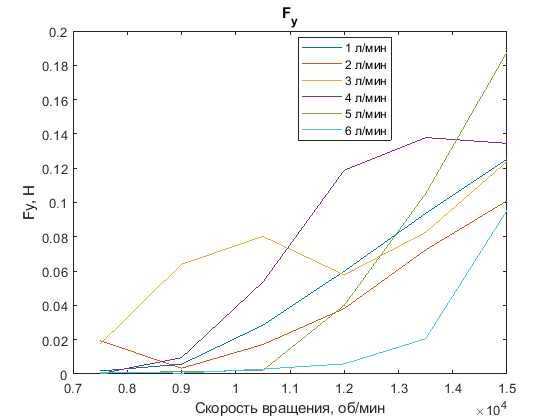

plot(RPM_comb,cell2mat(Fx_comb))

% subplot(2,2,2)
title('F_y')
xlabel('Скорость вращения, об/мин')
ylabel('Fy, Н')
legend({'1 л/мин','2 л/мин','3 л/мин','4 л/мин','5 л/мин','6 л/мин'},"Location","best")

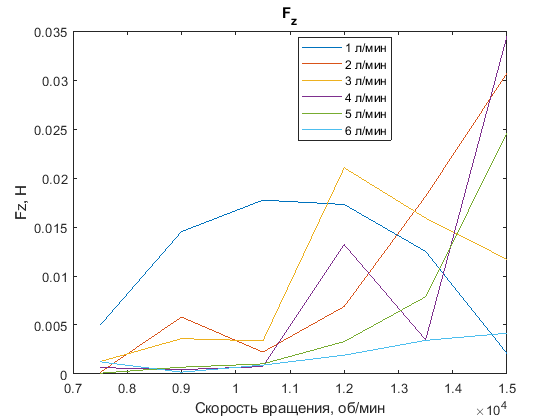

plot(RPM_comb,cell2mat(Fy_comb))

% figure("Name","Линейная интерполяция сил")
% subplot(2,2,3)
title('F_z')
xlabel('Скорость вращения, об/мин')
ylabel('Fz, Н')
legend({'1 л/мин','2 л/мин','3 л/мин','4 л/мин','5 л/мин','6 л/мин'},"Location","best")

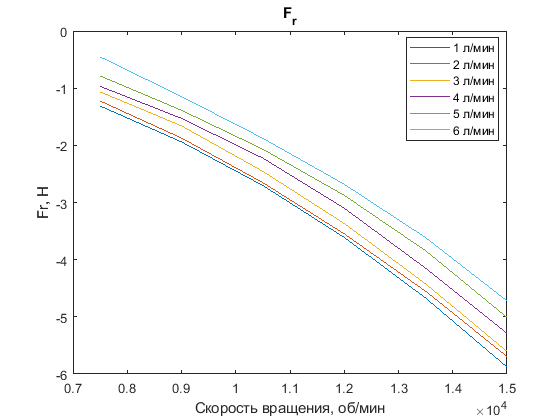

plot(RPM_comb,cell2mat(Fz_comb))

% subplot(2,2,4)
title('F_r')
xlabel('Скорость вращения, об/мин')
ylabel('Fr, Н')
legend({'1 л/мин','2 л/мин','3 л/мин','4 л/мин','5 л/мин','6 л/мин'},"Location","best")

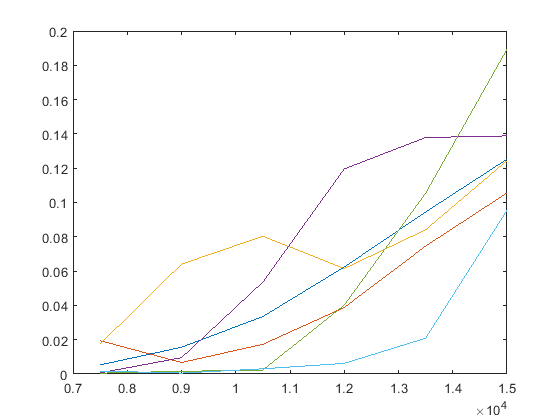

plot(RPM_comb,cell2mat(Fr_comb))



figure("Name","Линейная интерполяция моментов")
%1-D data interpolation 
subplot(2,2,1)
title('M_x')
xlabel('Скорость вращения, об/мин')
ylabel('Mx, Н*м')
legend({'1 л/мин','2 л/мин','3 л/мин','4 л/мин','5 л/мин','6 л/мин'},"Location","best")

plot(RPM_comb,cell2mat(Mx_comb))

subplot(2,2,2)
title('M_y')
xlabel('Скорость вращения, об/мин')
ylabel('My, Н*м')
legend({'1 л/мин','2 л/мин','3 л/мин','4 л/мин','5 л/мин','6 л/мин'},"Location","best")

plot(RPM_comb,cell2mat(My_comb))

subplot(2,2,3)
title('M_z')
xlabel('Скорость вращения, об/мин')
ylabel('Mz, Н*м')
legend({'1 л/мин','2 л/мин','3 л/мин','4 л/мин','5 л/мин','6 л/мин'},"Location","best")

plot(RPM_comb,cell2mat(Mz_comb))

subplot(2,2,4)
title('M_r')
xlabel('Скорость вращения, об/мин')
ylabel('Mr, Н*м')
legend({'1 л/мин','2 л/мин','3 л/мин','4 л/мин','5 л/мин','6 л/мин'},"Location","best")

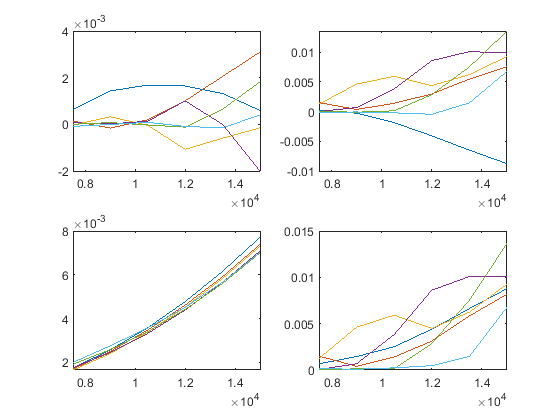

plot(RPM_comb,cell2mat(Mr_comb))


save curvefitting.mat

Кубическая интерполяция

% figure("Name","Кубическая интерполяция сил")
% xq = 6500:14500;
% % vq = interp1(RPM,Fz,'pchip');
% figure
% vq1 = interp1(RPM,Fz,xq,'pchip');
% plot(RPM,Fz,'o',xq,vq1,':.');
% % xlim([0 2*pi]);
% title('(Default) Linear Interpolation');

% title('F_x')
% xlabel('Скорость вращения, об/мин')
% ylabel('Fx, Н')
% legend({'1 л/мин','2 л/мин','3 л/мин','4 л/мин','5 л/мин','6 л/мин'},"Location","best")
% plot(RPM_comb,cell2mat(Fx_comb))


% x = [1 2 3 4 5];
% v = [12 16 31 10 6];
% xq = [0 0.5 1.5 5.5 6];
% vq1 = interp1(x,v,xq,'pchip')

% xlabel('Скорость вращения, об/мин')
% ylabel('Fx, Н')
% legend({'1 л/мин','2 л/мин','3 л/мин','4 л/мин','5 л/мин','6 л/мин'},"Location","northwest")
% plot(RPM_comb,cell2mat(Fx_comb))
% title('F_x')



% figure
% hold on
% hlines = plot(RPM_comb,cell2mat(Fx_comb))
% % hlines = plot(cell2mat(Fx_comb(:, 2:end))')
% % [hlines.DisplayName] = Fx_comb{:, 1};
% legend('show');

% cellfun(@plot,);
%pchip - кубическая интерполяция
%Define the query points to be a finer sampling over the range of x.
% xq = min(RPM):1500:max(RPM); %query points
%plot()
%vq1 = interp1(RPM,Fz);
%plot(RPM,Fz,'o',RPM,vq1,':.');
%xlim([min(RPM) max(RPM)]);
%%title('(Default) Linear Interpolation');
% title('Линейная интерполяция')
%линейная интерполяция
% interp1q